% add the necessary files to the path (this should be all that is required)
addpath(genpath(pwd))
addpath(genpath(fullfile(fileparts(pwd),'data')))
addpath(genpath(fullfile(fileparts(pwd),'utils')))

# Prerequisites, do not ignore!

We have included a fork of [deeplab-pytorch](https://github.com/kazuto1011/deeplab-pytorch) within this repo.  It must still be installed and configured to run with MATLAB. 

We recommend against using a virtual enviroment because it can be more complex to make it compatible with MATLAB. However it is not impossible to tell MATLAB to use a specific environment, it is just more stable with the base Anaconda environment. Once everything is downloaded and installed the original authors of [deeplab-pytorch](https://github.com/kazuto1011/deeplab-pytorch) recommended using these commands in the Anaconda prompt:

We recommend just opening the file: `deeplab-pytorch-master/configs/conda_env.yaml `and manually installing the dependencies. 

You will also need to install `pydensecrf `which can be done from the Anaconda prompt with this command. 

You will then need to install the pretrained model weights, but are likely to have trouble using wget. So you may manually download the weights at the URLs indicated in the file `deeplab-pytorch-master/scripts/setup_caffemodels.sh` and place them where indicated. 

The bash script which downloads the weights can be run like this:

After placing the model weights in the right folders you will need to run convert.py on the coco dataset

Only now can you expect MATLAB to run this code, and that is IF you configured MATLAB to work with python correctly. See other tutorial xxx

# Analyzing image content with a resNet image segmentation and labeling network trained on the COCO-stuff data set

Site the paper, site coco-stuff, site the models

Up a the top you will find controls for the text which let you control font properties and text type. Next to that is the code section, you switch between code and text by clicking those controls or using the "alt-enter" shortcut. 

To insert math you click the "insert tab" and you find options for equations. You will also find the ability to insert image insertion, and table of contents. 

Images and figures are embedded in to this document. You don't have to do a thing. All plots, figures, and print-statements are embedded. It is for this reason that it is highly recommended to keep your code blocks short and use plenty of text above and below them to explain what is happening. Don't write a paper though. 1-5 sentences is almost always sufficient.

The code output is put on the side by default. This can be hard to read, it is recommended to use the "output inline" option which you find in the "view" tab. 

## Single image example

First we will provide an example of running the segmentation and labeling on a single image. This will help you to understand the flow and how data is stored. 

#### Output the segmentation maps

 % There is a test image already located in the fork of deeplab-pytorch
 % you need only to provide a path to the image, see the help for what parameters are available. These are as used in Rose et al. 
 imagePath=".\image.jpg"
[maps,resNetParams]=getLabelMaps(imagePath)

`maps.labelMapList` has 10 slices on the third dimension. Each slice is one iteration from our modifications to the segmentation and labeling process. The original process assigned one label to each pixel. Here we simply repeat that process, but for each iteration we eliminate the most widely assigned labels. Thus, for most pixels the labeling process is forced to pick a different label at each iteration. 

`maps.probMapList` has 182 slices on the forth dimension in addition to the 10 slices on the third. The resNet actually assigns a probability distribution over labels and there are 182 labels for the COCO-stuff data set. In order to pick just one label for each pixel the original model used a "conditional random field" to assess what label had the highest probability for each pixel and take into account the neighbors of that pixel. So all we really did was to force more and more labels to have the lowest probability with each iteration. 

#### Output the widely applied labels

% just provide the outputs of the previous functions
[cloud]=convertMaps2Wordcloud(maps,resNetParams)

`cloud.sortedClassNames` is a list indicating which of the 182 COC-stuff labels were widely assigned throughout the assignment iterations. It is in order from first iteration (most confident) to last generation (least confident). 

`cloud.sortedLabels` is the same as `cloud.sortedClassNames`, except is a numerical index into the set of 182. 

`cloud.labelLayer` specifically identifies the iteration (AKA the "layer") in which the assignment was made. 

`cloud.segImSize` is the size of the image that was segmented.

#### Output relationships between layers

It helps to get a sense of how the algorithm thinks labels are related in an image. This function gives you several adjacency matrices showing pairwise relationships between all identified labels. It also provides the centroids of the labels. This is used for plotting. 

[adjMat]=getLabelRelationships(cloud,maps)

`adjMat.labelNetworkOverlap` indicates the ratio of the number of pixels that occur in both of two labels relative to the total number of pixels in those labels.

`adjMat.labelNetworkOverlapDir` indicates the ratio of the number of pixels that occur in both of two labels relative to the number of pixels in only one of those labels (the label on the row).

`adjMat.labelNetworkJointProb` indicates the product of all pixelwise probabilities of the labels on the row and column. 

`adjMat.labelNetworkRelEnt` indicates the relative entropy between two labels relative to the label on the row.

`adjMat.labelLocMap` applies the first assigned label to each pixel in the original image.

`adjMat.labelClusts` identifies a hierarchical clustering of labels, to identify which labels have a lot in common.

`adjMat.labelCentroids` is the column, and row of the centroid of the labels in `adjMat.labelLocMap` 

#### Visualize the label relationships and the labels in the image

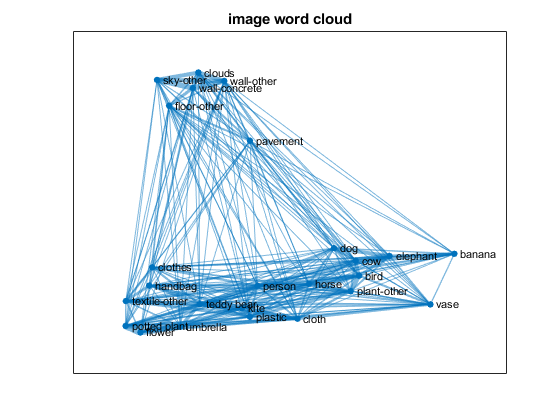

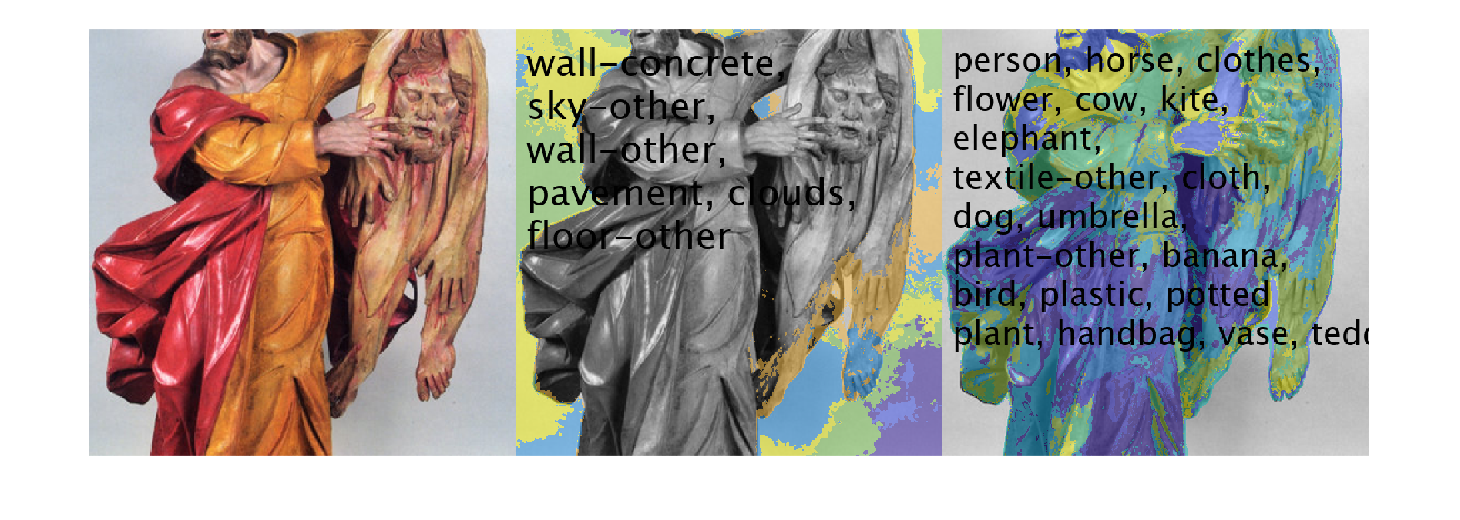

imagePath=fullfile('.\deeplab-pytorch-master',resNetParams.imagePath);
visualizeSingleSemanticLabelCloud(imagePath,cloud.labelLayer,cloud.sortedClassNames,adjMat.labelLocMap,adjMat.labelNetworkOverlap);

## Example with set of images

Having obtained a set of labels for a single image we now demonstrate counting label occurance frequencies in two sets of images. 

% two small samples from AlexNet
daisies=dir('..\data\daisy\*.JPEG');
macaques=dir('..\data\macaque\*.JPEG');
imPaths={fullfile({daisies.folder},{daisies.name}),fullfile({macaques.folder},{macaques.name})};


[classNames,hierarchyLabels]=getClassesYHierarchy();
data2Analyze=cell(size(imPaths));

% get labels and count them without regard to hierarchy
% Note: In our experience, to run this loop in parallel you need separate MATLAB sessions or else you run into stability issues (hangs).
labelCounts=zeros(length(imPaths),length(classNames));
for imType=1:length(imPaths)
    data2Analyze{imType}=cell(1,length(imPaths{imType}));
    for imNdx=1:length(imPaths{imType})
        [maps,resNetParams]=getLabelMaps(imPaths{imType}{imNdx});
        [data2Analyze{imType}{imNdx}]=convertMaps2Wordcloud(maps,resNetParams);
        labelCounts(imType,data2Analyze{imType}{imNdx}.sortedLabels+1)=labelCounts(imType,data2Analyze{imType}{imNdx}.sortedLabels+1)+1;
    end
end

Device: CPU
Model: DeepLabV2_ResNet101_MSC
Device: CPU
Model: DeepLabV2_ResNet101_MSC
Device: CPU
Model: DeepLabV2_ResNet101_MSC


Index in position 2 is invalid. Array indices must be positive integers or logical values.

labelFreqs=labelCounts./sum(labelCounts,2);

% print all the labels and their frequencies for each category
daisyReport=cellfun(@(x) [classNames{x},' = ',num2str(labelCounts(1,x)),';     '],num2cell(1:length(classNames)),'Uni',false);
macaqueReport=cellfun(@(x) [classNames{x},' = ',num2str(labelCounts(1,x)),';     '],num2cell(1:length(classNames)),'Uni',false);

disp(['Daisy, all label counts: ',newline,strjoin(daisyReport,''),newline])
disp(['Macaque, all label counts: ',newline,strjoin(macaqueReport,''),newline])

In the above we can see that there are a lot of labels and some small differences. It will help to group labels by similarity. Thankfully, the COCO-stuff data set provides a hierarchy for doing so.

% now re-group the labels by the 3rd level of the hierarchy
pick3rd=@(x) x(1:3);
hierarchyLabels2=hierarchyLabels;
hierarchyNdcsOriginal=grp2idx(hierarchyLabels2);
hierarchyLabels2=categorical(cellfun(@(x) strjoin(fliplr(pick3rd(strsplit(x,' '))),' '),hierarchyLabels2,'Uni',false));
categories2Plot=categories(hierarchyLabels2);
hierarchyNdcs=grp2idx(hierarchyLabels2);

hierarchLabelCounts=zeros([length(imPaths),length(categories2Plot)]);
for imType=1:length(imPaths)
        hierarchLabelCounts(imType,:)=accumarray(hierarchyNdcs,labelCounts(imType,:),@sum);
end
hierarchLabelFreqs=hierarchLabelCounts./sum(hierarchLabelCounts,2);


% print all the labels and their frequencies for each category
daisyReport=cellfun(@(x) [hierarchyLabels2{x},' = ',num2str(hierarchLabelCounts(1,x)),';     '],num2cell(1:length(hierarchyLabels2)),'Uni',false);
macaqueReport=cellfun(@(x) [hierarchyLabels2{x},' = ',num2str(hierarchLabelCounts(1,x)),';     '],num2cell(1:length(hierarchyLabels2)),'Uni',false);

disp(['Daisy, hierarchy label counts: ',newline,strjoin(daisyReport,''),newline])
disp(['Macaque, hierarchy label counts: ',newline,strjoin(macaqueReport,''),newline])

While this is easier to interpret there are still many categories and there seems to be a level of noise. It is best to focus only on the labels which rise above the noise. Here we identify those labels and then apply a chi-square test to find differences. 


% get only the labels distinguishable from zero
labelFreqSTD=std(hierarchLabelFreqs,[],2);
keepVec=hierarchLabelFreqs>(2*labelFreqSTD); keepVec=any(keepVec,[2,3]);
classes2Plot=find(keepVec);
categories2Plot=categories2Plot(classes2Plot);
hierarchLabelFreqsK=hierarchLabelFreqs(:,classes2Plot);
hierarchLabelCountsK=hierarchLabelCounts(:,classes2Plot);

% step through and get the chi square test and odds ratio
nFiles=sum(cellfun(@length,imPaths));
labelStats3rdLevel=cell(length(categories2Plot));
imTypeList=zeros(1,nFiles);
binaryLabelOccurance=zeros(length(classNames),nFiles);
fndx=0;
for imType=1:length(imPaths)
    for imNdx=1:length(imPaths{imType})
fndx=fndx+1;
        imTypeList(fndx)=imType;
        binaryLabelOccurance(data2Analyze{imType}{imNdx}.sortedLabels+1,fndx)=1;
    end
end
    for labelNdx=1:length(categories2Plot)
        labelRemapping=unique(hierarchyNdcsOriginal(hierarchyNdcs==classes2Plot(labelNdx)));
        binaryHierarchLabelOccurance=binaryLabelOccurance(labelRemapping,:); binaryHierarchLabelOccurance=sum(binaryHierarchLabelOccurance,1)~=0;
        [tbl,chi2,p]=crosstab(binaryHierarchLabelOccurance,imTypeList);
        [~,p2,stats]=fishertest(tbl);
        labelStats3rdLevel{labelNdx}={chi2,p,stats,p2,tbl};
    end
labelOccuranceDiffs=-diff(hierarchLabelFreqsK,[],1);

[~,sortedNdcs]=sort(labelOccuranceDiffs,'descend');
categories2Plot=categories2Plot(sortedNdcs);
categories2Plot2=reordercats(categorical(categories2Plot),categories2Plot);
hierarchLabelFreqsK=hierarchLabelFreqsK(sortedNdcs);
hierarchLabelCountsK=hierarchLabelCountsK(sortedNdcs);
labelStats3rdLevel=labelStats3rdLevel(sortedNdcs);
labelOccuranceDiffs=labelOccuranceDiffs(sortedNdcs);

ax=axes();
b=bar(ax,categories2Plot2,labelOccuranceDiffs);
b(1).FaceColor=[1,1,1];
b(1).LineWidth=1;
title('Patch interpretations')
% xtickLabels=ax.XTickLabel;
xtickLabels=cellfun(@(x) pick1st(strsplit(x,' ')),categories2Plot,'Uni',false);
sigLevels=cellfun(@(x) (length(categories2Plot)*x{2})<0.05/27,labelStats3rdLevel(:,1));
xtickLabels(sigLevels)=cellfun(@(x) ['*',x],xtickLabels(sigLevels),'Uni',false);
ax.XTickLabel=xtickLabels;
ax.YTick=[-0.04,0,0.04];
ax.YLabel.String={'label frequency','difference'};
ax.YLim=[-0.042,0.041];
ax.YLabel.Position=[-1.1070   -0.0161   -1.0000];



statisticsReport=cellfun(@(x) [categories2Plot{x},': Chi-square = ',num2str(labelStats3rdLevel{x}{1}),', p = ',num2str(labelStats3rdLevel{x}{2}),';     '],num2cell(1:length(categories2Plot)),'Uni',false);

disp(['Chi-square statistics: ',newline,strjoin(statisticsReport,''),newline])


The bar chart shows the relative enrichment of one label in the daisy category over the macaque category if values are positive. The reverse is true for negative values. We have also printed the exact chi-square values that correspond to the bon-ferroni significance indicated with * in the plot labels.

# Functions

These are the functions that do all the hardwork. Inspect them to gain a deeper understanding. Copy them for your own use, so long as you cite us!

function [maps,resNetParams]=getLabelMaps(imagePath,resNetParams)

if nargin<2 || ~isstruct(resNetParams)
configPath=".\configs\cocostuff164k.yaml";
modelPath=".\data\models\coco\deeplabv1_resnet101\caffemodel\deeplabv2_resnet101_msc-cocostuff164k-100000.pth";

resNetParams=struct('configPath',configPath,'modelPath',modelPath,'imagePath',imagePath,'cuda',false,'crf',true,'sizeThresh',1/9,'maxIteration',10);
end
doPlot=false;

try
    originalDir=pwd;
    cd(".\deeplab-pytorch-master")
catch
    cd("..")
    cd("..")
    originalDir=pwd;
    cd(".\deeplab-pytorch-master")
end
[a]=py.singleHierarchy.singleHierarchy(resNetParams.configPath,resNetParams.modelPath,imagePath,resNetParams.cuda,resNetParams.crf,resNetParams.sizeThresh,resNetParams.maxIteration,doPlot);
imagePath='';
cd(originalDir)

a=cell(a);
maps.labelMapList=cellfun(@(x) double(x), cell(a{1}),'Uni',false); maps.labelMapList=cat(3,maps.labelMapList{:});
maps.probMapList=cellfun(@(x) double(x), cell(a{2}),'Uni',false);  maps.probMapList=permute(cat(4,maps.probMapList{:}),[2,3,4,1]);
maps.classList=a{3};

end


    
function [cloud]=convertMaps2Wordcloud(maps,resNetParams)

    % get a list of all the labels represeneted
    unqLabels=unique(maps.labelMapList(:));
    unqClassNames=cellfun( @(x) char(maps.classList{x}),num2cell(unqLabels),'Uni',false);
    maps.classList=[];
    labelEdges=(unqLabels(1:end-1)+unqLabels(2:end))/2; labelEdges=[unqLabels(1);labelEdges;unqLabels(end)];
    % step through the label maps
    cloud.nLayers=size(maps.labelMapList,3);
    cloud.segImSize=size(maps.labelMapList,[1,2]);
    cloud.sortedLabels=[];
    cloud.sortedClassNames={};
    cloud.labelLayer=[];
    unWrap=@(x) x(:);
    for layer=1:cloud.nLayers
        % keep the unique values which cover more than 1/9th of the image
        N=histcounts(unWrap(maps.labelMapList(:,:,layer)),labelEdges,'Normalization','probability');
        bigLabels=unqLabels(N>=resNetParams.sizeThresh);
        bigClassNames=unqClassNames(N>=resNetParams.sizeThresh);
        % sort them by size and keep track of what level they are in
        % append them to the previous level
        [~,sortNdcs]=sort(N(N>=resNetParams.sizeThresh),'descend');
        cloud.labelLayer=[cloud.labelLayer;layer*ones(size(bigLabels))];
        cloud.sortedLabels=[cloud.sortedLabels;bigLabels(sortNdcs)];
        cloud.sortedClassNames=[cloud.sortedClassNames;bigClassNames(sortNdcs)];
    end
    cloud.nLabels=numel(cloud.sortedLabels);
end


function [adjMat]=getLabelRelationships(cloud,maps)
    
    
    % make a blank adjacency matrix
    adjMat.labelNetworkOverlap=zeros(cloud.nLabels);
    adjMat.labelNetworkOverlapDir=zeros(cloud.nLabels);
    adjMat.labelNetworkJointProb=zeros(cloud.nLabels);
    adjMat.labelNetworkRelEnt=zeros(cloud.nLabels);
    % make a deep boolean matrix representing the locations of all the labels represented (in order of the list)
    labelLocs=false([size(maps.labelMapList,[1,2]),numel(cloud.sortedLabels)]);
    probMap=squeeze(maps.probMapList(:,:,1,:)); probMap=probMap./sum(probMap,[1,2]);
    adjMat.labelLocMap=zeros(size(maps.labelMapList,[1,2])); % the sums in this map are uniquely defined by a combination of other layers
    sumLabelCodes=ones(1,cloud.nLabels);
    for labelNdx=1:cloud.nLabels
        label=cloud.sortedLabels(labelNdx);
        labelLocs(:,:,labelNdx)=any(maps.labelMapList==label,3);
        adjMat.labelLocMap(labelLocs(:,:,labelNdx))=adjMat.labelLocMap(labelLocs(:,:,labelNdx))+sumLabelCodes(labelNdx);
        if labelNdx<cloud.nLabels
            sumLabelCodes(labelNdx+1)=sum(sumLabelCodes(1:labelNdx))+1;
        end
    end
    % step through the labels and make the strength of the connection equal to the overlap of sections
    % we could also use joint distribution metrics (KL-divergence, mutual information, etc)
    for rowNdx=1:cloud.nLabels
        for colNdx=1:cloud.nLabels
            if rowNdx==colNdx; continue; end
            if rowNdx>=colNdx
                adjMat.labelNetworkOverlap(rowNdx,colNdx)=sum(labelLocs(:,:,rowNdx) & labelLocs(:,:,colNdx) ,'all')./sum(labelLocs(:,:,rowNdx) | labelLocs(:,:,colNdx) ,'all');
                adjMat.labelNetworkOverlap(colNdx,rowNdx)=adjMat.labelNetworkOverlap(rowNdx,colNdx);
                adjMat.labelNetworkJointProb(rowNdx,colNdx)=sum(exp(log(probMap(:,:,rowNdx))+log(probMap(:,:,colNdx))),'all'); % prevents some round off errors
                adjMat.labelNetworkJointProb(colNdx,rowNdx)=adjMat.labelNetworkJointProb(rowNdx,colNdx);
            end
            adjMat.labelNetworkOverlapDir(rowNdx,colNdx)=sum(labelLocs(:,:,rowNdx) & labelLocs(:,:,colNdx) ,'all')./sum(labelLocs(:,:,rowNdx),'all');
            adjMat.labelNetworkRelEnt(rowNdx,colNdx)=sum(probMap(:,:,rowNdx).*(log(probMap(:,:,rowNdx))-log(probMap(:,:,colNdx))),'all');
        end
    end
    adjMat.labelNetworkOverlap(logical(eye(size(adjMat.labelNetworkOverlap))))=1;
    
    numClusts=min(2,sum(cloud.labelLayer==1));
    [adjMat.labelClusts]=cluster(linkage(squareform(1-adjMat.labelNetworkOverlap),'average'),'maxclust',numClusts);
    
    % visualize by tying each label to it's segment centroid (avoid collisions)
    % step through the labels and get their probability weighted locations
    [cols,rows]=meshgrid(1:cloud.segImSize(2),1:cloud.segImSize(1));
    adjMat.labelCentroids=zeros(cloud.nLabels,2);
    for labelNdx=1:cloud.nLabels
        label=cloud.sortedLabels(labelNdx);
        probMap=maps.probMapList(:,:,1,label+1);
        probMap=probMap(:)./sum(probMap(:));
        adjMat.labelCentroids(labelNdx,:)=round(sum([rows(:).*probMap,cols(:).*probMap],1));
    end
end



function visualizeSingleSemanticLabelCloud(imagePath,labelLayer,sortedClassNames,labelLocMap,labelNetworkAdj)

nLabels=length(labelLayer);
labelLocs=getLabelLocsFromMap(nLabels,labelLocMap);

unDir=all(labelNetworkAdj==labelNetworkAdj',"all");
if unDir
    graphObj=graph(labelNetworkAdj,sortedClassNames,'omitselfloops');
else
    graphObj=digraph(labelNetworkAdj,sortedClassNames,'omitselfloops');
end
labelNetworkAdj=(~eye(size(labelNetworkAdj))).*(labelNetworkAdj+labelNetworkAdj)/2 + eye(size(labelNetworkAdj))*max(labelNetworkAdj(:));
LWidths = 5*graphObj.Edges.Weight/max(graphObj.Edges.Weight);

figure()
p=plot(graphObj,'LineWidth',LWidths,'Layout','force','WeightEffect','inverse');
title('image word cloud')



figure() % plot the main clusters in the image
numClusts=min(2,sum(labelLayer==1));
[splits]=cluster(linkage(squareform(max(labelNetworkAdj(:))-labelNetworkAdj),'average'),'maxclust',numClusts);
numClusts=numel(unique(splits));
if numClusts==1;
numClusts=min(2,sum(labelLayer==1))+1;
[splits]=cluster(linkage(squareform(max(labelNetworkAdj(:))-labelNetworkAdj),'average'),'maxclust',numClusts);
numClusts=numel(unique(splits));
end

if ~isnumeric(imagePath)
    originalImage=imresize(imread(imagePath),size(labelLocMap,[1,2]));
else
    originalImage=imresize(imagePath,size(labelLocMap,[1,2]));
end
grayVersion=repmat(rgb2gray(originalImage),[1,1,3]);
imSize=size(originalImage);
clustMasks=zeros([size(labelLocMap,[1,2]),numClusts]);
clustClouds=cell(1,numClusts);
clustIms=cell(1,numClusts);
for ndx=1:numClusts
    clustMasks(:,:,ndx)=sum(labelLocs(:,:,splits==ndx),3);
    clustClouds{ndx}=sortedClassNames(splits==ndx);
    heatMapOverlay=labeloverlay(grayVersion,clustMasks(:,:,ndx),'Colormap','parula');
    FontSize=round(40+40/length(clustClouds{ndx}));
    % make sure the text fits in the image
    fontWidth=FontSize/2;
    imWidth=ceil(imSize(2)/fontWidth);
    cloudString=strjoin(clustClouds{ndx},', ');
    if length(cloudString)>=imWidth;
        nParts=ceil(length(cloudString)/imWidth);
        newLineLocs=zeros(1,nParts);
        temp=strfind(cloudString,' ');
        if length(temp)<nParts; temp=[temp,length(cloudString)+1]; end
        for insertCnt=1:nParts
            if insertCnt==1
                newLineLocs(insertCnt)=temp(find(temp<((insertCnt-1)*(imWidth-1)+imWidth) & temp>((insertCnt-1)*(imWidth-1)+1),1,'last'));
            else
                newLineLocs(insertCnt)=temp(find(temp<(newLineLocs(insertCnt-1)+imWidth) & temp>newLineLocs(insertCnt-1),1,'last'));
            end
        end
        cloudString(newLineLocs)=newline;
    end
    clustIms{ndx}=insertText(heatMapOverlay,[0,0],cloudString,'BoxOpacity',0,'TextColor',[1,0.97,0.95],'FontSize',FontSize-2);
end
if numClusts<4
montage([originalImage,clustIms],'Size',[1,numClusts+1])
else
montage([originalImage,clustIms])
end
drawnow

end


function labelLocs2=getLabelLocsFromMap(nLabels,labelLocMap)


sumLabelCodes=ones(1,nLabels);
for labelNdx=1:nLabels
    if labelNdx<nLabels
        sumLabelCodes(labelNdx+1)=sum(sumLabelCodes(1:labelNdx))+1;
    end
end
factorList=cell(nLabels,1);
for labNdx=1:nLabels
    factorList{labNdx}=factor(sumLabelCodes(labNdx));
end


isOdd=mod(labelLocMap,2)==1;
labelLocMap2=labelLocMap;
labelLocMap2(isOdd)=max(1,labelLocMap2(isOdd)-1);
labelLocs2=(labelLocMap2==permute(sumLabelCodes,[1,3,2]));
labelLocs2(:,:,1)=labelLocs2(:,:,1)  |  isOdd ;
uniqueSums=unique(labelLocMap2(:));
uniqueSums=setdiff(uniqueSums,sumLabelCodes);
uniqueSums=sort(uniqueSums,'descend');

nSums=numel(uniqueSums);
sumComps=cell(1,nSums);
foundsums=[];
missingSums=uniqueSums;
for sumNdx=1:nSums
    if ~isempty(sumComps{sumNdx}); continue; end
    sumVal=uniqueSums(sumNdx);
    
    % see if the sum has only one component
    knownComponents=sumLabelCodes(sumLabelCodes==sumVal);
    if isempty(knownComponents)
        possibleComponents=sort(sumLabelCodes(sumLabelCodes>1 & sumLabelCodes<sumVal),'descend');
        if sum(possibleComponents)==sumVal % see if the sum is all possible components
            knownComponents=possibleComponents;
        else
            % test all possible combinations
            compRows=possibleComponents'; % the first combination is just the one possible component so the "component rows" is width==1
            sumTest=sum(compRows,2);
            cnt=0;
            while ~any(sumTest==sumVal)
                cnt=cnt+1;
                % make a matrix of the sum of prior combinations  with another set of possible components
                [rows,cols]=meshgrid(1:size(compRows,1),possibleComponents);
                sumTest=possibleComponents'+sumTest'; % here is the matrix
                indexer=sumTest<=sumVal; % get rid of values larger than the sum
                sumTest=sumTest(indexer);
                compRows=sort([compRows(rows(indexer),:),cols(indexer)],2); % list the expanded set of combinations we just tested
                [compRows,indexer]=unique(compRows,'rows'); % the order of components doesn't matter so keep unique rows
                indexer=indexer(~any(diff(compRows,[],2)==0,2)); % no component can be repeated 2 or more times so get rid of repeats
                sumTest=sumTest(indexer);
                compRows=compRows(~any(diff(compRows,[],2)==0,2),:);
                % we might not have found the combination for the sum we are checking but we might have stumbled across another
                checkSums=sumTest==missingSums';
                if any(checkSums,'all')
                    foundSumNdcs=setdiff(find(any(checkSums,1)),foundsums);
                    foundsums=unique([foundSumNdcs,foundsums]);
                    missingSums(foundsums)=0;
                    % disp(['found ',num2str(length(foundSumNdcs)),' other sums'])
                    for foundSumNdx=foundSumNdcs
                        if ~isempty(sumComps{foundSumNdx}); continue; end
                        sumComps{foundSumNdx}=compRows(sum(compRows,2)==uniqueSums(foundSumNdx),:);
                        if size(sumComps{foundSumNdx},1)~=1; error('the labelLocMap is inconsistent with the number of labels'); end
                    end
                end
            end
            knownComponents=compRows(sum(compRows,2)==sumVal,:);
            if size(knownComponents,1)~=1; error('the labelLocMap is inconsistent with the number of labels'); end
        end
    end
    sumComps{sumNdx}=knownComponents;
end

for sumNdx=1:nSums
    knownComponents=sumComps{sumNdx};
    sumVal=uniqueSums(sumNdx);
    labelLocs2(:,:,ismember(sumLabelCodes,knownComponents))=labelLocs2(:,:,ismember(sumLabelCodes,knownComponents)) | labelLocMap2==sumVal;
end

end






function [classNames,hierarchyLabels]=getClassesYHierarchy()



parentsStuff = { ...
    'stuff', 'stuff'; ...
    ... % End of level 1
    'indoor-super-stuff', 'stuff'; ...
    'outdoor-super-stuff', 'stuff'; ...
    ... % End of level 2
    'rawmaterial-stuff', 'indoor-super-stuff'; ...
    'wall-stuff', 'indoor-super-stuff'; ...
    'ceiling-stuff', 'indoor-super-stuff'; ...
    'floor-stuff', 'indoor-super-stuff'; ...
    'window-stuff', 'indoor-super-stuff'; ...
    'furniture-stuff', 'indoor-super-stuff'; ...
    'textile-stuff', 'indoor-super-stuff'; ...
    'food-stuff', 'indoor-super-stuff'; ...
    'building-stuff', 'outdoor-super-stuff'; ...
    'structural-stuff', 'outdoor-super-stuff'; ...
    'plant-stuff', 'outdoor-super-stuff'; ...
    'sky-stuff', 'outdoor-super-stuff'; ...
    'solid-stuff', 'outdoor-super-stuff'; ...
    'ground-stuff', 'outdoor-super-stuff'; ...
    'water-stuff', 'outdoor-super-stuff'; ...
    ... % End of level 3
    'cardboard', 'rawmaterial-stuff'; ...
    'paper', 'rawmaterial-stuff'; ...
    'plastic', 'rawmaterial-stuff'; ...
    'metal', 'rawmaterial-stuff'; ...
    'wall-tile', 'wall-stuff'; ...
    'wall-panel', 'wall-stuff'; ...
    'wall-wood', 'wall-stuff'; ...
    'wall-brick', 'wall-stuff'; ...
    'wall-stone', 'wall-stuff'; ...
    'wall-concrete', 'wall-stuff'; ...
    'wall-other', 'wall-stuff'; ...
    'ceiling-tile', 'ceiling-stuff'; ...
    'ceiling-other', 'ceiling-stuff'; ...
    'carpet', 'floor-stuff'; ...
    'floor-tile', 'floor-stuff'; ...
    'floor-wood', 'floor-stuff'; ...
    'floor-marble', 'floor-stuff'; ...
    'floor-stone', 'floor-stuff'; ...
    'floor-other', 'floor-stuff'; ...
    'window-blind', 'window-stuff'; ...
    'window-other', 'window-stuff'; ...
    'door-stuff', 'furniture-stuff'; ...
    'desk-stuff', 'furniture-stuff'; ...
    'table', 'furniture-stuff'; ...
    'shelf', 'furniture-stuff'; ...
    'cabinet', 'furniture-stuff'; ...
    'cupboard', 'furniture-stuff'; ...
    'mirror-stuff', 'furniture-stuff'; ...
    'counter', 'furniture-stuff'; ...
    'light', 'furniture-stuff'; ...
    'stairs', 'furniture-stuff'; ...
    'furniture-other', 'furniture-stuff'; ...
    'rug', 'textile-stuff'; ...
    'mat', 'textile-stuff'; ...
    'towel', 'textile-stuff'; ...
    'napkin', 'textile-stuff'; ...
    'clothes', 'textile-stuff'; ...
    'cloth', 'textile-stuff'; ...
    'curtain', 'textile-stuff'; ...
    'blanket', 'textile-stuff'; ...
    'pillow', 'textile-stuff'; ...
    'banner', 'textile-stuff'; ...
    'textile-other', 'textile-stuff'; ...
    'fruit', 'food-stuff'; ...
    'salad', 'food-stuff'; ...
    'vegetable', 'food-stuff'; ...
    'food-other', 'food-stuff'; ...
    ... % End of level 4 left
    'house', 'building-stuff'; ...
    'skyscraper', 'building-stuff'; ...
    'bridge', 'building-stuff'; ...
    'tent', 'building-stuff'; ...
    'roof', 'building-stuff'; ...
    'building-other', 'building-stuff'; ...
    'fence', 'structural-stuff'; ...
    'cage', 'structural-stuff'; ...
    'net', 'structural-stuff'; ...
    'railing', 'structural-stuff'; ...
    'structural-other', 'structural-stuff'; ...
    'grass', 'plant-stuff'; ...
    'tree', 'plant-stuff'; ...
    'bush', 'plant-stuff'; ...
    'leaves', 'plant-stuff'; ...
    'flower', 'plant-stuff'; ...
    'branch', 'plant-stuff'; ...
    'moss', 'plant-stuff'; ...
    'straw', 'plant-stuff'; ...
    'plant-other', 'plant-stuff'; ...
    'clouds', 'sky-stuff'; ...
    'sky-other', 'sky-stuff'; ...
    'wood', 'solid-stuff'; ...
    'rock', 'solid-stuff'; ...
    'stone', 'solid-stuff'; ...
    'mountain', 'solid-stuff'; ...
    'hill', 'solid-stuff'; ...
    'solid-other', 'solid-stuff'; ...
    'sand', 'ground-stuff'; ...
    'snow', 'ground-stuff'; ...
    'dirt', 'ground-stuff'; ...
    'mud', 'ground-stuff'; ...
    'gravel', 'ground-stuff'; ...
    'road', 'ground-stuff'; ...
    'pavement', 'ground-stuff'; ...
    'railroad', 'ground-stuff'; ...
    'platform', 'ground-stuff'; ...
    'playingfield', 'ground-stuff'; ...
    'ground-other', 'ground-stuff'; ...
    'fog', 'water-stuff'; ...
    'river', 'water-stuff'; ...
    'sea', 'water-stuff'; ...
    'waterdrops', 'water-stuff'; ...
    'water-other', 'water-stuff'; ...
    };



parentsThings = { ...
    'things', 'things'; ...
    ... % End of level 1
    'indoor-super-things', 'things'; ...
    'outdoor-super-things', 'things'; ...
    ... % End of level 2
    'person-things', 'outdoor-super-things'; ...
    'vehicle-things', 'outdoor-super-things'; ...
    'outdoor-things', 'outdoor-super-things'; ...
    'animal-things', 'outdoor-super-things'; ...
    'accessory-things', 'outdoor-super-things'; ...
    'sports-things', 'outdoor-super-things'; ...
    'kitchen-things', 'indoor-super-things'; ...
    'food-things', 'indoor-super-things'; ...
    'furniture-things', 'indoor-super-things'; ...
    'electronic-things', 'indoor-super-things'; ...
    'appliance-things', 'indoor-super-things'; ...
    'indoor-things', 'indoor-super-things'; ...
    ... % End of level 3
    'person', 'person-things'; ...
    'bicycle', 'vehicle-things'; ...
    'car', 'vehicle-things'; ...
    'motorcycle', 'vehicle-things'; ...
    'airplane', 'vehicle-things'; ...
    'bus', 'vehicle-things'; ...
    'train', 'vehicle-things'; ...
    'truck', 'vehicle-things'; ...
    'boat', 'vehicle-things'; ...
    'traffic light', 'outdoor-things'; ...
    'fire hydrant', 'outdoor-things'; ...
    'street sign', 'outdoor-things'; ...
    'stop sign', 'outdoor-things'; ...
    'parking meter', 'outdoor-things'; ...
    'bench', 'outdoor-things'; ...
    'bird', 'animal-things'; ...
    'cat', 'animal-things'; ...
    'dog', 'animal-things'; ...
    'horse', 'animal-things'; ...
    'sheep', 'animal-things'; ...
    'cow', 'animal-things'; ...
    'elephant', 'animal-things'; ...
    'bear', 'animal-things'; ...
    'zebra', 'animal-things'; ...
    'giraffe', 'animal-things'; ...
    'hat', 'accessory-things'; ...
    'backpack', 'accessory-things'; ...
    'umbrella', 'accessory-things'; ...
    'shoe', 'accessory-things'; ...
    'eye glasses', 'accessory-things'; ...
    'handbag', 'accessory-things'; ...
    'tie', 'accessory-things'; ...
    'suitcase', 'accessory-things'; ...
    'frisbee', 'sports-things'; ...
    'skis', 'sports-things'; ...
    'snowboard', 'sports-things'; ...
    'sports ball', 'sports-things'; ...
    'kite', 'sports-things'; ...
    'baseball bat', 'sports-things'; ...
    'baseball glove', 'sports-things'; ...
    'skateboard', 'sports-things'; ...
    'surfboard', 'sports-things'; ...
    'tennis racket', 'sports-things'; ...
    'bottle', 'kitchen-things'; ...
    'plate', 'kitchen-things'; ...
    'wine glass', 'kitchen-things'; ...
    'cup', 'kitchen-things'; ...
    'fork', 'kitchen-things'; ...
    'knife', 'kitchen-things'; ...
    'spoon', 'kitchen-things'; ...
    'bowl', 'kitchen-things'; ...
    'banana', 'food-things'; ...
    'apple', 'food-things'; ...
    'sandwich', 'food-things'; ...
    'orange', 'food-things'; ...
    'broccoli', 'food-things'; ...
    'carrot', 'food-things'; ...
    'hot dog', 'food-things'; ...
    'pizza', 'food-things'; ...
    'donut', 'food-things'; ...
    'cake', 'food-things'; ...
    'chair', 'furniture-things'; ...
    'couch', 'furniture-things'; ...
    'potted plant', 'furniture-things'; ...
    'bed', 'furniture-things'; ...
    'mirror', 'furniture-things'; ...
    'dining table', 'furniture-things'; ...
    'window', 'furniture-things'; ...
    'desk', 'furniture-things'; ...
    'toilet', 'furniture-things'; ...
    'door', 'furniture-things'
    'tv', 'electronic-things'; ...
    'laptop', 'electronic-things'; ...
    'mouse', 'electronic-things'; ...
    'remote', 'electronic-things'; ...
    'keyboard', 'electronic-things'; ...
    'cell phone', 'electronic-things'; ...
    'microwave', 'appliance-things'; ...
    'oven', 'appliance-things'; ...
    'toaster', 'appliance-things'; ...
    'sink', 'appliance-things'; ...
    'refrigerator', 'appliance-things'; ...
    'blender', 'appliance-things'; ...
    'book', 'indoor-things'; ...
    'clock', 'indoor-things'; ...
    'vase', 'indoor-things'; ...
    'scissors', 'indoor-things'; ...
    'teddy bear', 'indoor-things'; ...
    'hair drier', 'indoor-things'; ...
    'toothbrush', 'indoor-things'; ...
    'hair brush', 'indoor-things'; ...
    };


classNames={'person', 'bicycle', 'car', 'motorcycle', 'airplane', 'bus', 'train', 'truck', 'boat', 'traffic light', 'fire hydrant', 'street sign',...
    'stop sign', 'parking meter', 'bench', 'bird', 'cat', 'dog', 'horse', 'sheep', 'cow', 'elephant', 'bear', 'zebra', 'giraffe', 'hat', 'backpack',...
    'umbrella', 'shoe', 'eye glasses', 'handbag', 'tie', 'suitcase', 'frisbee', 'skis', 'snowboard', 'sports ball', 'kite', 'baseball bat',...
    'baseball glove', 'skateboard', 'surfboard', 'tennis racket', 'bottle', 'plate', 'wine glass', 'cup', 'fork', 'knife', 'spoon', 'bowl',...
    'banana', 'apple', 'sandwich', 'orange', 'broccoli', 'carrot', 'hot dog', 'pizza', 'donut', 'cake', 'chair', 'couch', 'potted plant', 'bed',...
    'mirror', 'dining table', 'window', 'desk', 'toilet', 'door', 'tv', 'laptop', 'mouse', 'remote', 'keyboard', 'cell phone', 'microwave', 'oven',...
    'toaster', 'sink', 'refrigerator', 'blender', 'book', 'clock', 'vase', 'scissors', 'teddy bear', 'hair drier', 'toothbrush', 'hair brush',...
    'banner', 'blanket', 'branch', 'bridge', 'building-other', 'bush', 'cabinet', 'cage', 'cardboard', 'carpet', 'ceiling-other', 'ceiling-tile',...
    'cloth', 'clothes', 'clouds', 'counter', 'cupboard', 'curtain', 'desk-stuff', 'dirt', 'door-stuff', 'fence', 'floor-marble', 'floor-other',...
    'floor-stone', 'floor-tile', 'floor-wood', 'flower', 'fog', 'food-other', 'fruit', 'furniture-other', 'grass', 'gravel', 'ground-other', 'hill',...
    'house', 'leaves', 'light', 'mat', 'metal', 'mirror-stuff', 'moss', 'mountain', 'mud', 'napkin', 'net', 'paper', 'pavement', 'pillow',...
    'plant-other', 'plastic', 'platform', 'playingfield', 'railing', 'railroad', 'river', 'road', 'rock', 'roof', 'rug', 'salad', 'sand', 'sea',...
    'shelf', 'sky-other', 'skyscraper', 'snow', 'solid-other', 'stairs', 'stone', 'straw', 'structural-other', 'table', 'tent', 'textile-other',...
    'towel', 'tree', 'vegetable', 'wall-brick', 'wall-concrete', 'wall-other', 'wall-panel', 'wall-stone', 'wall-tile', 'wall-wood', 'water-other',...
    'waterdrops', 'window-blind', 'window-other', 'wood'};

parents=[parentsStuff;parentsThings];
classParents=cell(length(classNames),3);
for cNdx=1:length(classNames)
    locationsInHierarchy=find(strcmpi(parents(:,1),classNames{cNdx}));
    if length(locationsInHierarchy)~=1
        dsafasdf
    end
    classParents{cNdx,1}=parents{locationsInHierarchy,2};
    locationsInHierarchy=find(strcmpi(parents(:,1),classParents{cNdx,1}));
    if length(locationsInHierarchy)~=1
        dsafasdf2
    end
    classParents{cNdx,2}=parents{locationsInHierarchy,2};
    locationsInHierarchy=find(strcmpi(parents(:,1),classParents{cNdx,2}));
    if length(locationsInHierarchy)~=1
        dsafasdf2
    end
    classParents{cNdx,3}=parents{locationsInHierarchy,2};
end

hierarchyLabels=classNames;
for cNdx=1:length(classNames)
    hierarchyLabels{cNdx}=[classParents{cNdx,3},' ',classParents{cNdx,2}(1:(strfind(classParents{cNdx,2},'-')-1)),' ',classParents{cNdx,1}(1:(strfind(classParents{cNdx,1},'-')-1)),' ',classNames{cNdx}];
end


end












